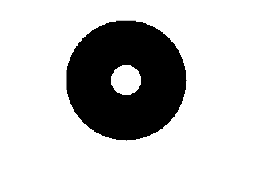

clc, clear
% Läs in bild
image = imread("colorful.jpg");
image = im2double(image);

% Ta ut storlek på bild
[heigth, width] = size(image(:,:,1));

% Storlek på pärlorna (minst 7 pixlar för att det ska vara en pärla)
pearlDia = 150;
% Threshold för optimisering för paletterna (lägre min_deltaE ger mindre filtrering)
min_deltaE = 15;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% Skapa pärla
pearl = createPearl(pearlDia);
imshow(pearl)

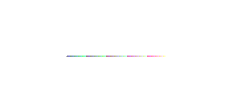

% Skapa palletter
[pallete, opt_Pallette, opt2_Pallette] = palette(min_deltaE, image);
[rand_Pallette, opt_rand_Pallette,opt2_rand_Pallette] = random_palette(125, min_deltaE,image);

% Visa alla paletter 
imshow(pallete);

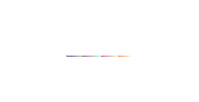

imshow(opt_Pallette);

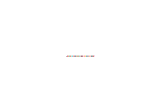

imshow(opt2_Pallette);

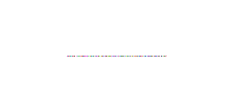

imshow(rand_Pallette);

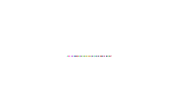

imshow(opt_rand_Pallette);

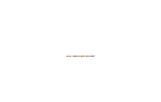

imshow(opt2_rand_Pallette);

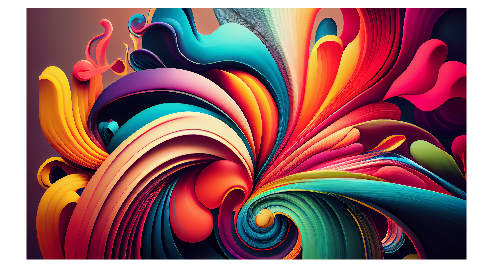


% Ändra storleken på bilden så att varje pixel blir en pärla
resizedImage = imresize(image, [ceil(heigth/pearlDia), ceil(width/pearlDia)]);

% Hitta rätt färg för pärlan för den angivna paletten
image2 = findColorPalette(resizedImage, pallete);
image2_opt = findColorPalette(resizedImage, opt_Pallette);
image2_opt2 = findColorPalette(resizedImage, opt2_Pallette);

image2_rand = findColorPalette(resizedImage, rand_Pallette);
image2_opt_rand = findColorPalette(resizedImage, opt_rand_Pallette);
image2_opt2_rand = findColorPalette(resizedImage, opt2_rand_Pallette);

% Skapa pärlbilden
finalImage = create_photo(pearl,pearlDia, image2);
finalImage_opt = create_photo(pearl,pearlDia, image2_opt);
finalImage_opt2 = create_photo(pearl, pearlDia, image2_opt2);

finalImage_rand = create_photo(pearl,pearlDia, image2_rand);
finalImage_rand_opt = create_photo(pearl,pearlDia, image2_opt_rand);
finalImage_rand_opt2 = create_photo(pearl,pearlDia, image2_opt2_rand);

imshow(image);

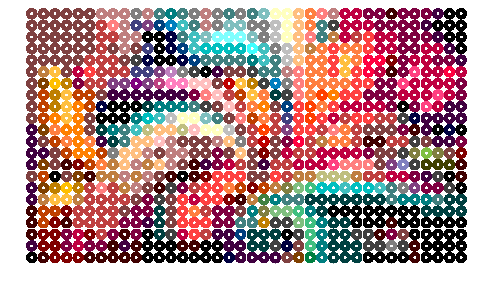


imshow(finalImage);

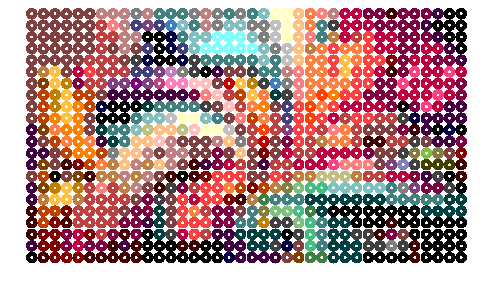

imshow(finalImage_opt);

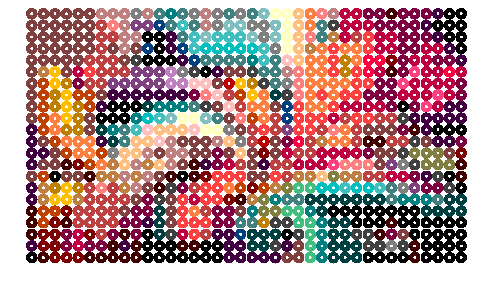

imshow(finalImage_opt2);

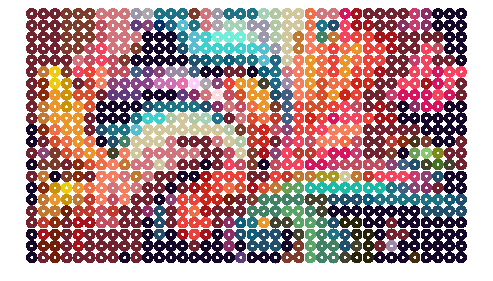


imshow(finalImage_rand);

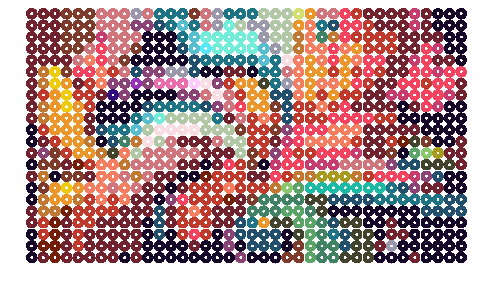

imshow(finalImage_rand_opt);

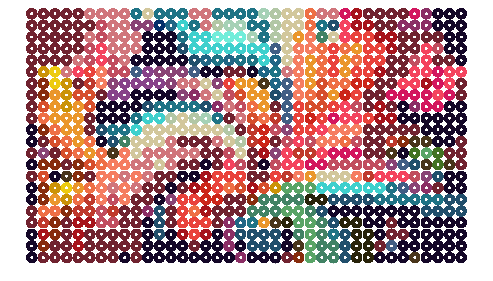

imshow(finalImage_rand_opt2);

% SCIELAB
result1 = calculate_scielab(image, image);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("original: " + result1);

original: 0



result2 = calculate_scielab(finalImage, image);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("Color pallette: " + result2);

Color pallette: 3.966



result3 = calculate_scielab(finalImage_opt, image);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("Optimized color pallette: " + result3);

Optimized color pallette: 3.9719



result4 = calculate_scielab(finalImage_opt2, image);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("Optimized color pallette from most used colors: " + result4);

Optimized color pallette from most used colors: 4.2235



result5 = calculate_scielab(finalImage_rand, image);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("Random color pallette: " + result5);

Random color pallette: 3.9647



result6 = calculate_scielab(finalImage_rand_opt, image);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("Random optimized color pallette: " + result6);

Random optimized color pallette: 3.9863



result7 = calculate_scielab(finalImage_rand_opt2, image);

Performing color transformations ...
Preparing filters ...
Filtering BW plane of image1 ...
Filtering RG plane of image1 ...
Filtering BY plane of image1 ...
Filtering BW plane of image2 ...
Filtering RG plane of image2 ...
Filtering BY plane of image2 ...
Computing CIELAB differences ...


disp("Random optimized color pallette from most used colors: " + result7);

Random optimized color pallette from most used colors: 4.3868


% deltaE
test = calculate_halftones(image, image);
disp("This compares the difference between original image (schould be 0): " + test)

This compares the difference between original image (schould be 0): 0



pallette = calculate_halftones(finalImage, image);
disp("Color pallette: " + pallette)

Color pallette: 41.9497



pallette_opt = calculate_halftones(finalImage_opt, image);
disp("Optimized color pallette: " + pallette_opt)

Optimized color pallette: 42.0506



pallette_opt2 = calculate_halftones(finalImage_opt2, image);
disp("Optimized color pallette from most used colors: " + pallette_opt2)

Optimized color pallette from most used colors: 45.6863



pallette_rand = calculate_halftones(finalImage_rand, image);
disp("Random color pallette: " + pallette_rand)

Random color pallette: 41.9064



rand_opt = calculate_halftones(finalImage_rand_opt, image);
disp("Random optimized color pallette: " + rand_opt)

Random optimized color pallette: 42.1391



rand_opt2 = calculate_halftones(finalImage_rand_opt2, image);
disp("Random optimized color pallette from most used colors: " + rand_opt2)

Random optimized color pallette from most used colors: 47.3325


% Räkna ut snr
snr = calculate_snr(image, image)

snr = Inf


snr_pallette = calculate_snr(finalImage, image)

snr_pallette = 1.2350

snr_pallette_opt = calculate_snr(finalImage_opt, image)

snr_pallette_opt = 1.2190

snr_pallette_opt2 = calculate_snr(finalImage_opt2, image)

snr_pallette_opt2 = 1.0155

snr_pallette_rand = calculate_snr(finalImage_rand, image)

snr_pallette_rand = 1.2477

snr_finalImage_rand_opt = calculate_snr(finalImage_rand_opt, image)

snr_finalImage_rand_opt = 1.2274

snr_finalImage_rand_opt2 = calculate_snr(finalImage_rand_opt2, image)

snr_finalImage_rand_opt2 = 1.0971


% imwrite(finalImage,'sv_finalImage.jpg');
% imwrite(finalImage_opt,'sv_finalImage_opt.jpg');
% imwrite(finalImage_rand,'sv_finalImage_rand5.jpg');
% imwrite(finalImage_rand_opt,'sv_finalImage_rand5_opt.jpg');
